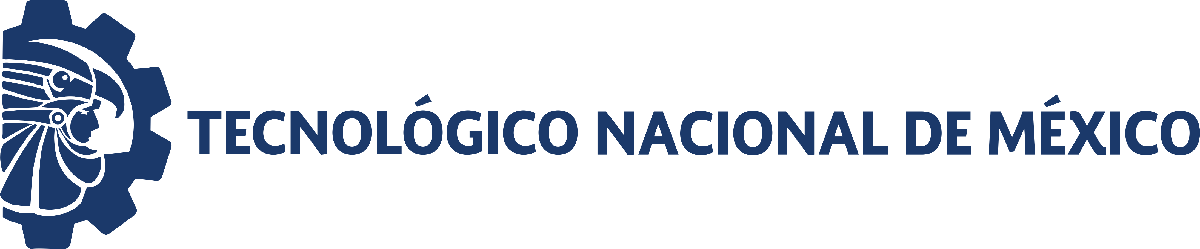                                 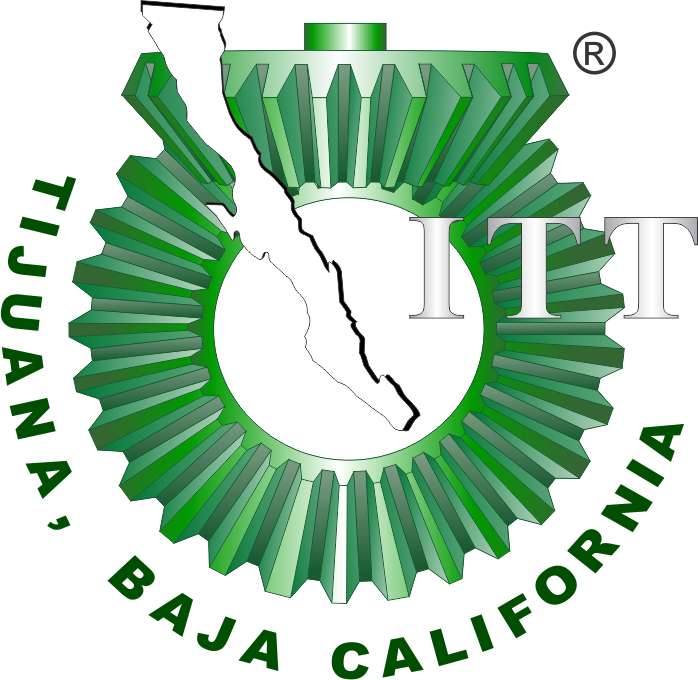

# **Práctica tres: Sistema Cardiovascular**

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

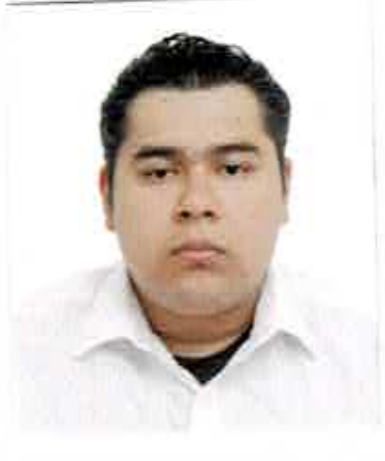

Nombre del alumno: **Mauricio Jesús Meraz Galeana**

Número de control: **18210139**

Correo institucional: **mauricio.meraz18@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos generales de la simulacion

clc; clear all; close all;
tend = '10';
file = 'SistemaP3';
open_system(file);
parametrer.StopTime = tend;
parameters.Solver = 'ode15s';


## Rendimiento del controlador Hipotenso  

kP = 0.0003333

KI = 413.332

kD =0

Rise time = 0.0054 s

settling time =0.0097 s

Overshoot = 0 %

Peak = 1 V

## Hipertenso

kP = 0.00022321

KI = 414.2852

kD =0

Rise time = 0.0054 s

settling time =0.0097 s

Overshoot = 0 %

Peak = 1 V

### **Respuesta la **función sinusoidal

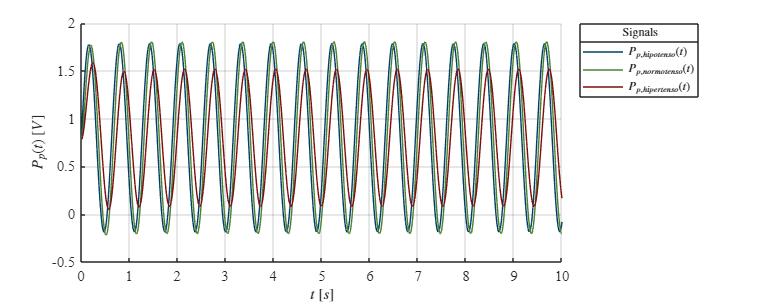

set_param('SistemaP3/Pa(t)','Amplitude','1');
set_param('SistemaP3/Pa(t)','Frequency','2*pi*95/60');
set_param('SistemaP3/Pa(t)','Bias','0.8');
N = sim(file,parameters);
plotsignals(N.t,N.Ppx,N.Ppy,N.Ppz)

### Hipotenso

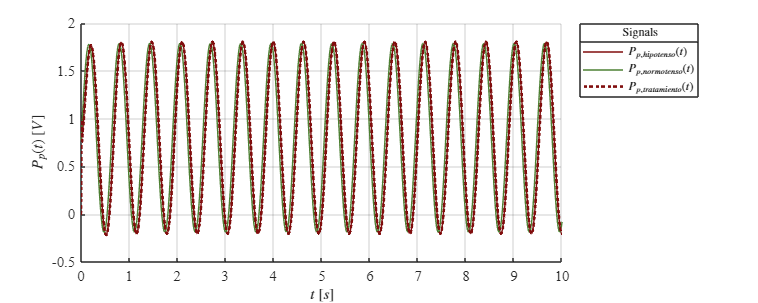

clc; clear all; close all;
tend = '10';
file = 'Hipotenso';
open_system(file);
parametrer.StopTime = tend;
parameters.Solver = 'ode15s';
X = sim(file,parameters);
plothipotenso(X.t,X.Py,X.Px,X.Pz)

### Hipertenso

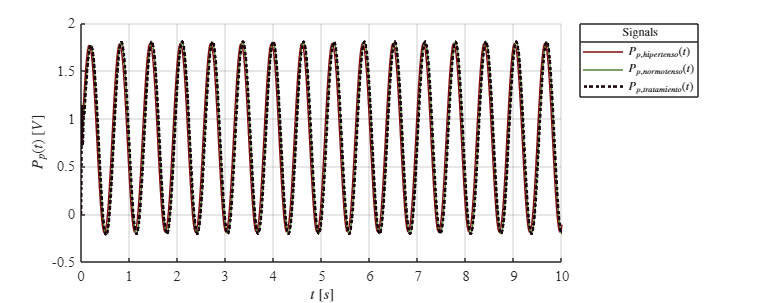

clc; clear all; close all;
tend = '10';
file = 'Hipertenso';
open_system(file);
parametrer.StopTime = tend;
parameters.Solver = 'ode15s';
Y = sim(file,parameters);
plothipertenso(Y.t,Y.Px,Y.Py,Y.Pz)

### Función: Respuesta a las señales

function plotsignals(t,Ppx,Ppy,Ppz)
set(figure(),'color','w')
set(gcf,'units','centimeters','position', [1,5,30,12])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid on


plot(t,Ppx,'LineWidth',0.5,'Color',[0,0.25,0.4])
plot(t,Ppy,'LineWidth',0.5,'Color',[0.3,0.5,0.2])
plot(t,Ppz,'LineWidth',0.5,'Color',[0.5,0.05,0.05])

L = legend('$P_{p,hipotenso}(t)$','$P_{p,normotenso}(t)$','$P_{p,hipertenso}(t)$'); 
set(L,'Interpreter','Latex','FontSize',9,'Location','NorthEastOutside')
title(L,'Signals')

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$P_p(t)$ $[V]$','Interpreter','Latex','FontSize',11)

xlim([0,10]); xticks(0:1:10)
ylim([-0.5,2]); yticks(-0.5:0.5:2)

name = 'simulink_sistema.pdf';
exportgraphics(gcf,name,'ContentType','Vector')
end

### Función: Tratamiento (Hipotenso)

function plothipotenso(t,Px,Py,Pz)
set(figure(),'color','w')
set(gcf,'units','centimeters','position', [1,5,30,12])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid on


plot(t,Px,'LineWidth',0.5,'Color',[0.5,0.05,0.05])
plot(t,Py,'LineWidth',0.5,'Color',[0.3,0.5,0.2])
plot(t,Pz,':','LineWidth',2,'Color',[0.5,0.05,0.05])

L = legend('$P_{p,hipotenso}(t)$','$P_{p,normotenso}(t)$','$P_{p,tratamiento}(t)$'); 
set(L,'Interpreter','Latex','FontSize',9,'Location','NorthEastOutside')
title(L,'Signals')

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$P_p(t)$ $[V]$','Interpreter','Latex','FontSize',11)

xlim([0,10]); xticks(0:1:10)
ylim([-0.5,2]); yticks(-0.5:0.5:2)

name = 'simulink_hipotenso.pdf';
exportgraphics(gcf,name,'ContentType','Vector')
end

### Función: Tratamiento (Hipertenso)

function plothipertenso(t,Px,Py,Pz)
set(figure(),'color','w')
set(gcf,'units','centimeters','position', [1,5,30,12])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid on


plot(t,Px,'LineWidth',0.5,'Color',[0.5,0.05,0.05])
plot(t,Py,'LineWidth',0.5,'Color',[0.3,0.5,0.2])
plot(t,Pz,':','LineWidth',2,'Color',[0.1,0.01,0.06])

L = legend('$P_{p,hipertenso}(t)$','$P_{p,normotenso}(t)$','$P_{p,tratamiento}(t)$'); 
set(L,'Interpreter','Latex','FontSize',9,'Location','NorthEastOutside')
title(L,'Signals')

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$P_p(t)$ $[V]$','Interpreter','Latex','FontSize',11)

xlim([0,10]); xticks(0:1:10)
ylim([-0.5,2]); yticks(-0.5:0.5:2)

name = 'simulink_hipertenso.pdf';
exportgraphics(gcf,name,'ContentType','Vector')
end